# Accumulated Errors and Compressor Speed

## Load data

clc; clear all

% Load a csv file from the data folder
data = readtable("data\Test_Atlanta_Default_MPC_Pretest_122723_1025.csv", 'PreserveVariableNames', true)

data = 16102×42 table
      Hardware Time Stamp      Simulation Time Step    WSHP Return Air Temp [°C]    WSHP Return Air RH [%RH]    WSHP Supply Air Temp [°C]    WSHP Supply Air RH [%RH]    WSHP Temp SP [°C]    WSHP Water Flowrate [kg/s]    Inlet Water Temp [°C]    Outlet Water Temp [°C]    WSHP Air Flowrate [cfm]    Meas Sensible Load [kW]    Meas Latent Load [kW]    WSHP Power [kW]    Sim Zone Temp [°C]    Sim Zone RH [%RH]    Sim Zone Dewpoint [°C]    Sim Outdoor Temp [°C]    Sim Outdoor RH [%RH]    Sim Outdoor Dewpoint [°C]    Sim Heat SP [°C]    Sim Cool SP [°C]    Sim Sensible Load [W]    

## Preprocessing

% Remove rows where 'Simulation Time Step' is <= 0 and >= 1339
idx = data.('Simulation Time Step') > 0 & data.('Simulation Time Step') < 1339;
data = data(idx, :);

% Eextract data
simulation_time_step = data.("Simulation Time Step")/60;
sim_zone_temp = data.("Sim Zone Temp [°C]");
active_setpoint = data.("Active Setpoint [°C]");
wshp_power = data.("WSHP Power [kW]");  % it is actually W
vdc = data.("CompSpd");

% Calculated values
acc_error = accumulated_errors(sim_zone_temp, active_setpoint, wshp_power, 150);

% Smooth the data
window_size = 12*15;
acc_error_avg = movmean(acc_error, window_size);
vdc_avg = movmean(vdc,window_size);

## Plot

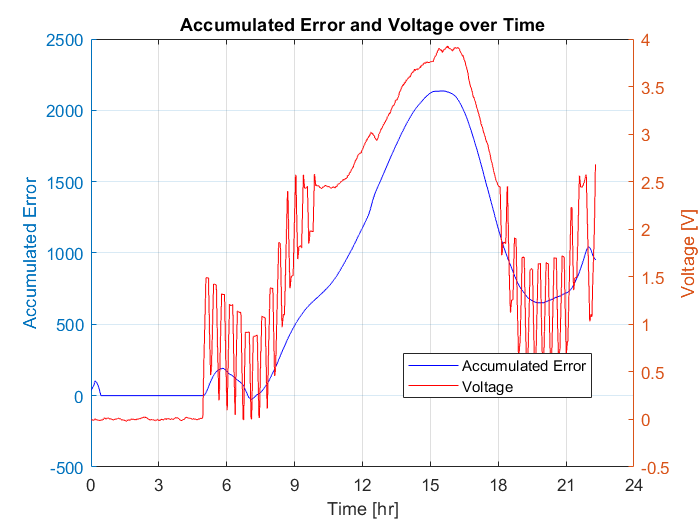

figure;

% Specify the left y-axis for the first data set
yyaxis left
plot(simulation_time_step, acc_error_avg, 'b-'); % 'b-' specifies a blue solid line
xlim([0 24]);
xticks(0:3:24);
xlabel('Time [hr]');
ylabel('Accumulated Error');
grid on

% Specify the right y-axis for the second data set
yyaxis right
plot(simulation_time_step, vdc_avg, 'r-'); % 'r-' specifies a red solid line
ylabel('Voltage [V]');

% Add legends and titles as necessary
legend('Accumulated Error', 'Voltage', 'Location', 'best');
title('Accumulated Error and Voltage over Time');